2.4a 创建函数

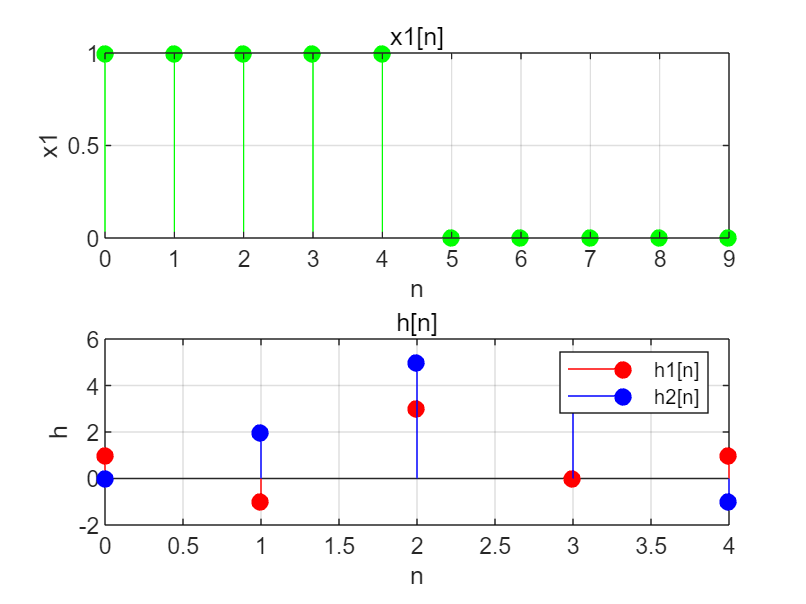

clc,clear,close all;
figure;
x1=[1 1 1 1 1 0 0 0 0 0];
nx=[0 1 2 3 4 5 6 7 8 9];
h1=[1 -1 3 0 1];
h2=[0 2 5 4 -1];
nh1=[0 1 2 3 4];
subplot(2,1,1),stem(nx,x1,'g','filled'),title('x1[n]'),xlabel('n'),ylabel('x1'),grid on,xlim([0 9]);
subplot(2,1,2);
stem(nh1,h1,'r','filled');
hold on;
stem(nh1,h2,'b','filled');
hold off;
legend('h1[n]','h2[n]'),grid on,xlabel('n'),ylabel('h'),title('h[n]');

2.4b x1*h1 h1*x1验证卷积交换律

分析：计算x1*h1、h1*x1，作图比较

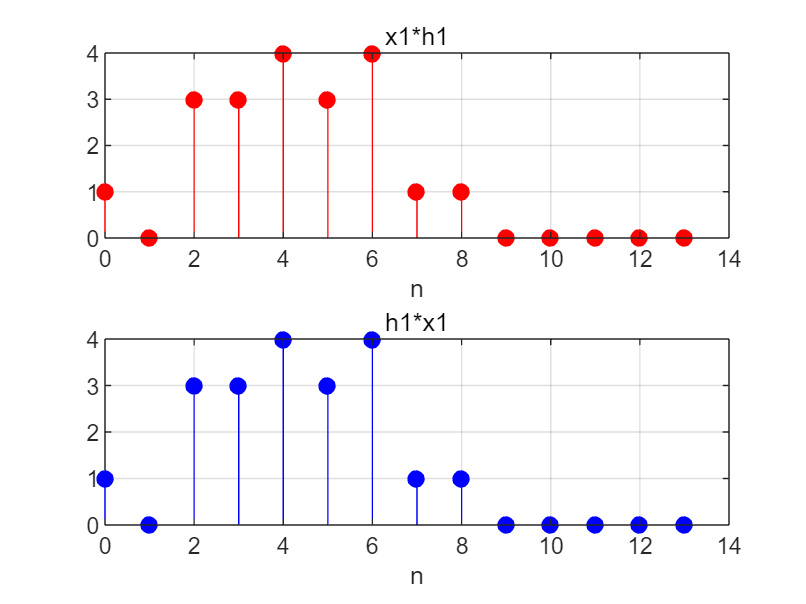

figure;
y1=conv(x1,h1);
ny1=nx(1)+nh1(1):nx(end)+nh1(end);
y2=conv(h1,x1);
ny2=nh1(1)+nx(1):nh1(end)+nx(end);
subplot(2,1,1),stem(ny1,y1,'r','filled'),grid on,xlabel('n'),title('x1*h1');
subplot(2,1,2),stem(ny2,y2,'b','filled'),grid on,xlabel('n'),title('h1*x1');

根据图像比较可得知：两图形相同，x1*h1=h1*x1，故卷积满足交换率。

2.4c 验证x[n] * (h1[n] + h2[n]) = x[n] * h1[n] + x[n] * h2[n]

分析：计算x1*(h1+h2)、x1*h1+x1*h2，作图比较

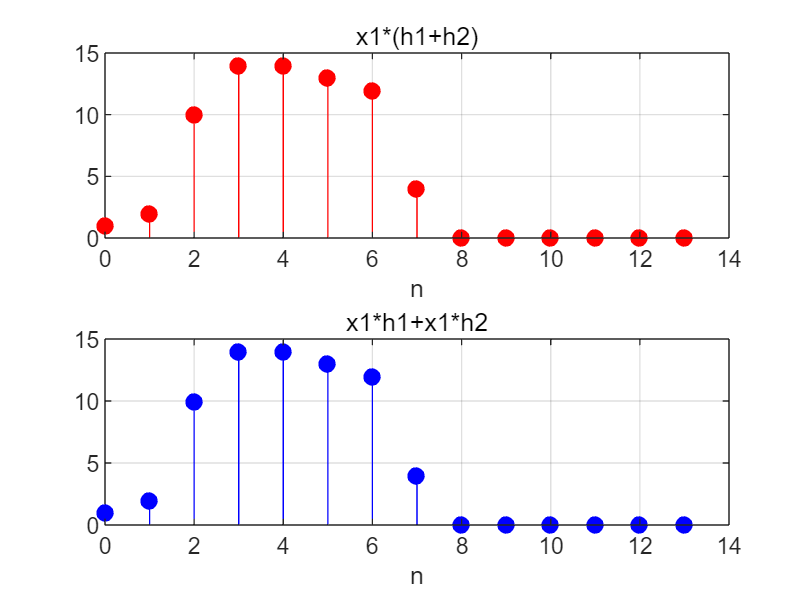

figure;
y3=conv(x1,h1+h2);
ny3=nx(1)+nh1(1):nx(end)+nh1(end);
y4=conv(x1,h1)+conv(x1,h2);
ny4=nx(1)+nh1(1):nx(end)+nh1(end);
subplot(2,1,1),stem(ny3,y3,'r','filled'),grid on,xlabel('n'),title('x1*(h1+h2)');
subplot(2,1,2),stem(ny4,y4,'b','filled'),grid on,xlabel('n'),title('x1*h1+x1*h2');

根据图像比较可得知：两图形相同，x1*(h1+h2)=x1*h1+x1*h2，故卷积满足分配率。

2.4d 验证(x[n] * h1[n]) * h2[n] = x[n] * (h1[n] * h2[n])

分析：计算(x[n] * h1[n]) * h2[n]、x[n] * (h1[n] * h2[n])，作图比较

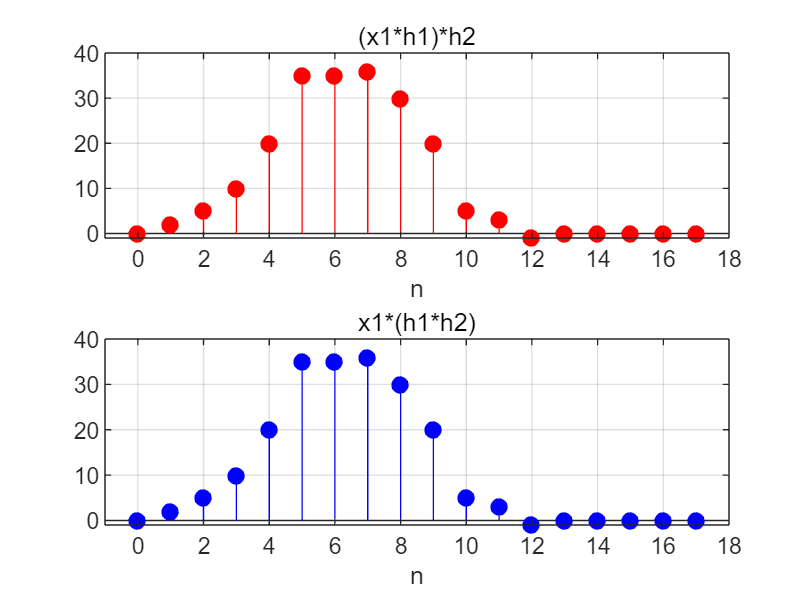

figure;
y5trans=conv(x1,h1);
y5=conv(y5trans,h2);
ny5=nx(1)+nh1(1)*2:nx(end)+nh1(end)*2;
y6trans=conv(h1,h2);
y6=conv(x1,y6trans);
ny6=nx(1)+nh1(1)*2:nx(end)+nh1(end)*2;
subplot(2,1,1),stem(ny5,y5,'r','filled'),grid on,xlabel('n'),title('(x1*h1)*h2'),xlim([-1 18]);
subplot(2,1,2),stem(ny6,y6,'b','filled'),grid on,xlabel('n'),title('x1*(h1*h2)'),xlim([-1 18]);

根据图像比较可得知：两图形相同，(x[n] * h1[n]) * h2[n] = x[n] * (h1[n] * h2[n])，故卷积满足结合率。

2.5e 证明时不变性

分析：按题目要求一步步构造函数ye1[n-n0]、ye2，作图比较

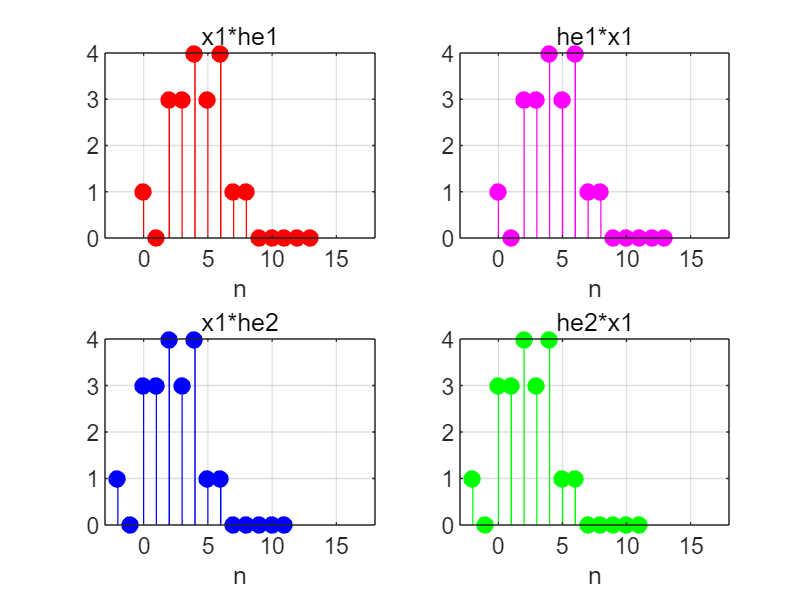

%构造函数
n0=2;
he1=h1;
nhe1=nh1;
he2=h1;
nhe2=nh1-n0;
%验证交换律
ye1=conv(x1,he1);
ye1inverse=conv(he1,x1);
nye1=nx(1)+nhe1(1):nx(end)+nhe1(end);
ye2=conv(x1,he2);
ye2inverse=conv(he2,x1);
nye2=nx(1)+nhe2(1):nx(end)+nhe2(end);
figure;
subplot(2,2,1),stem(nye1,ye1,'r','filled'),grid on,xlabel('n'),title('x1*he1'),xlim([-3 18]);
subplot(2,2,2),stem(nye1,ye1inverse,'m','filled'),grid on,xlabel('n'),title('he1*x1'),xlim([-3 18]);
subplot(2,2,3),stem(nye2,ye2,'b','filled'),grid on,xlabel('n'),title('x1*he2'),xlim([-3 18]);
subplot(2,2,4),stem(nye2,ye2inverse,'g','filled'),grid on,xlabel('n'),title('he2*x1'),xlim([-3 18]);

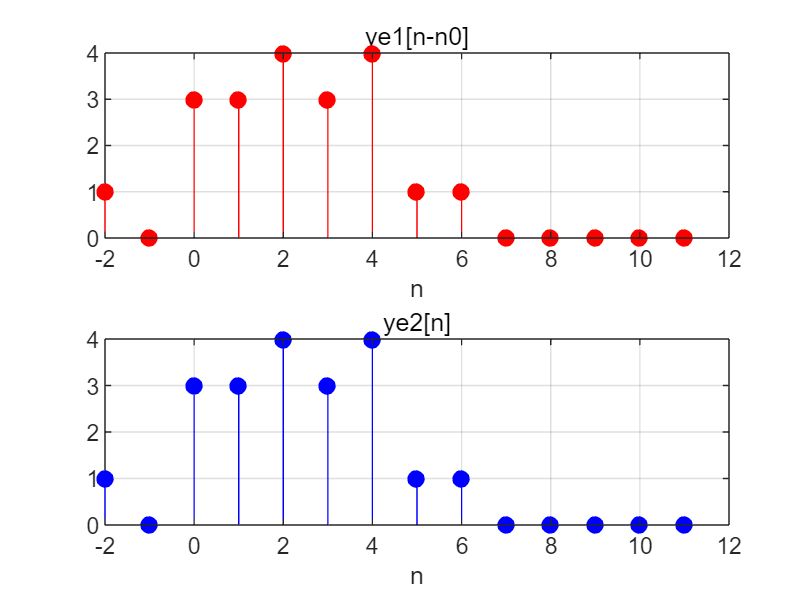

%验证时不变性
figure;
subplot(2,1,1),stem(nye1-n0,ye1,'r','filled'),grid on,xlabel('n'),title('ye1[n-n0]');
subplot(2,1,2),stem(nye2,ye2,'b','filled'),grid on,xlabel('n'),title('ye2[n]');

根据图像比较可得知：两图形相同，ye1[n-n0]=ye2[n]，故函数满足时不变性。